%% Skip to trial 9 %%%%%

%1
first = [-0.0169 0.2023 0.9791];
second = [0.6371 -0.7526 0.1667];
third = [0.7706 0.1667 -0.1163];
plot3(first(:,1), first(:,2), first(:,3), 'k*-', second(:,1), second(:,2), second(:,3), 'b^-', third(:,1), third(:,2), third(:,3), 'g>-');
legend({'first', 'second', 'third'})

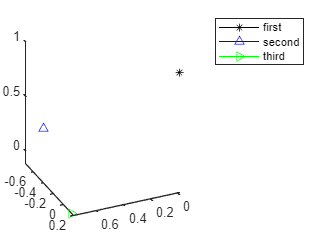

%2

point1 = [1,0,0];
point2 = [0,1,0];
point3 = [0 0 1];
point4= [1 2 3];
origin = [0,0,0];
figure;hold on;
plot3([origin(1) point1(1)],[origin(2) point1(2)],[origin(3) point1(3)],'LineWidth',5);
plot3([origin(1) point2(1)],[origin(2) point2(2)],[origin(3) point2(3)],'LineWidth',5);
plot3([origin(1) point3(1)],[origin(2) point3(2)],[origin(3) point3(3)],'LineWidth',5);
plot3([origin(1) point4(1)],[origin(2) point4(2)],[origin(3) point4(3)],'LineWidth',5);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gca,'CameraPosition',[2 2 2]);

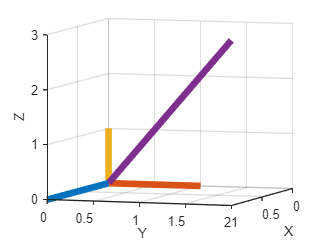

%3
rx = 30;

ry=5;
rz= 15;

%4
px = 20
py = 5
pz =10
P = [px py pz]
Rx = rotx(rx) ; %[X1 Y1 Z1];

px = 20

Ry = rotx(ry);%[X2 Y2 Z2];

py = 5

Rz = rotx(rz);

pz = 10

rotm = Rz*Ry*Rx;;

P =     20     5    10


eulZYX = rotm2eul(rotm);
disp(eulZYX)
origin = [0,0,0];
figure;hold on;
%plotOrientation(tp,rx,ry,rz,P) 
plot3([origin(1) eulZYX(1)],[origin(2) eulZYX(2)],[origin(3) eulZYX(3)],'LineWidth',5);

         0         0    0.8727



grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
%set(gca,'CameraPosition',[2 2 2]);

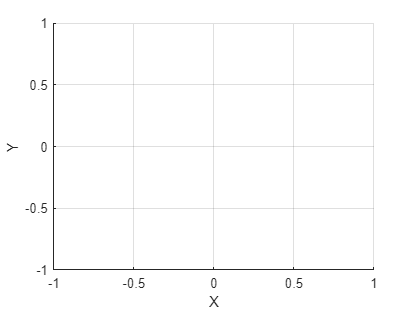

%5
rx = [20 10];
ry = [5 30];

rz =[20 10];

%7
beta = 5; alpha = 10;
Rz=@(x) [cosd(x),-sind(x),0 ; ...
        sind(x),cosd(x),0 ;...
        0 0 1];

px =      5     6     4     2     7


py =      2     8    10     3     4


pz =      1     2     3     4     5


m = 1

n = 5

toa =      0     1     2     3     4


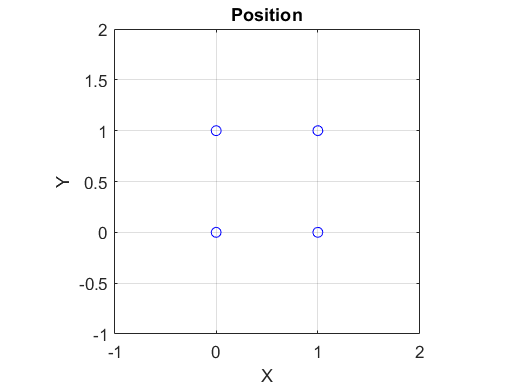

Ry = @(x) [cosd(x), 0, sind(x); 0 1 0; -sind(x), 0, cosd(x) ];

R=Ry(beta)*Rz(alpha); %ANGLES ARE IN DEGREES!!
[XpYp,XpZp,YpZp]=deal(R.'*2);
XpYp(3,:)=0; %X'Y'
XpZp(2,:)=0; %X'Z'
YpZp(1,:)=0; %Y'Z'
XpYp=R*XpYp;
XpZp=R*XpZp;
YpZp=R*YpZp;

%8
alpha = 5;
beta = 10;
gamma =20;
Ry = @(x) [cosd(x), 0, sind(x); 0 1 0; -sind(x), 0, cosd(x) ];
R = Rx(alpha)* Ry(beta)*Rz(gamma)


%%%%%%%% Next TRIAL9%%%

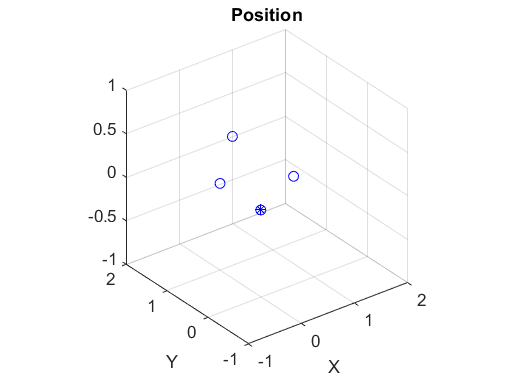

position = [0,0,0; ... % Initial position
             0,1,0; ...
             1,2,0; ...
             1,0.5,0; ...
             0,0,10];    % Final position

TimeInterval = 0:4; % time of arrival

orientation = quaternion([0,10,0; ...
                          45,0,0; ...
                          135,0,0; ...
                          225,0,0; ...
                          0,0,0], ...
                          'eulerd','ZYX','frame');
trajectory = waypointTrajectory(position, ...
    'TimeOfArrival', TimeInterval, ...
    'Orientation',orientation, ...
    'SampleRate',1);

figure
plot3(position(1,1),position(1,2),position(1,3),'b*')
title('Position')
axis([-1,2,-1,2])
axis square
xlabel('X')
ylabel('Y')
grid on
hold on

orientation1 = zeros(TimeInterval(end)*trajectory.SampleRate,1,'quaternion');
count = 1;
while ~isDone(trajectory)
   [Now,orientation1(count)] = trajectory();

   plot(Now(1),Now(2),'bo')

   pause(trajectory.SamplesPerFrame/trajectory.SampleRate)
   count = count + 1;
end
hold off




